# **EFTERÅR 2017 EKSAMEN**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**En diskret stokastisk variabel X kan antage værdierne**


$$\left\lbrace 0,\;1,\;2,\;3,\;4,\;5\right\rbrace$$


**med følgende sandsynligheder**


$$\begin{array}{l}
P\left(X=1\right)=P\left(X=2\right)=P\left(X=3\right)=0\ldotp 15,\\
P\left(X=4\right)=0\ldotp 25,\\
P\left(X=5\right)=0\ldotp 10
\end{array}$$


## 1.1 SANDSYNLIGHED

Bestemt sandsynligheden for at X har værdien 0 $P\left(X=0\right)$. 

Der anvendes, at arealet for en tæthedsfunktion er lig med 1, hvormed


$$\sum_{i=1}^n f_X \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


Da sandsynligheden for at X har værdien 0 er det sidste udfald, 

kan den findes ved at trække alle andre sandsynligheder fra summen som skal give 1.

PZero = 1 - (3*0.15 + 0.25 + 0.10);

disp("Sandsynligheden for at X har værdien 0 er lig med " + PZero);

Sandsynligheden for at X har værdien 0 er lig med 0.2


## 1.2 TÆTHEDS- OG FORDELINGSFUNKTION

Tæthedsfunktionen er bestemt ved


$$\sum_{i=1}^n f_X \left(x_i \right)=\sum_{i=1}^n P\left(X=x_i \right)=1$$


Fordelingsfunktionen er bestemt ved


$$F_X \left(x\right)=P\left(X\le x\right)$$


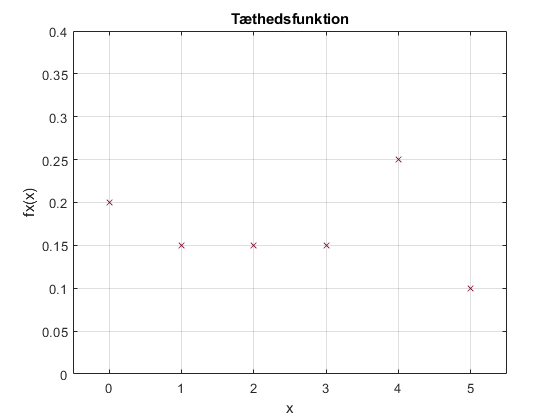

X = [0, 1, 2, 3, 4, 5];
P = [0.20, 0.15, 0.15, 0.15, 0.25, 0.10];
Pcdf = [0, 0, 0, 0, 0, 0];

figure(1)
stairs(X, P, 'x', 'Color', Color.DeepCleret);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
xlim([-0.50 5.50])
ylim([0.000 0.400])

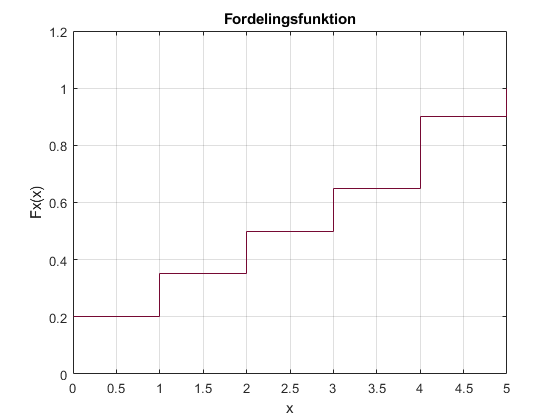


for n = 1:length(P)
    Pcdf(n) = sum(P(1:n));
end

figure(2)
stairs(X, Pcdf, 'Color', Color.DeepCleret);
grid on
title('Fordelingsfunktion')
ylabel('Fx(x)')
xlabel('x')
xlim([-0.00 5.00])
ylim([0.000 1.200])

## 1.3 MIDDELVÆRDI

Bestem middelværdien $E\left\lbrack X\right\rbrack$ af den stokastiske variabel X.

Dertil anvendes formlen for middelværdien af en stokastisk variabel som er givet ved


$$\bar{X} =E\left\lbrack X\right\rbrack =\sum_{i=1}^n x_i \cdot f_X \left(x_i \right)$$


EstimationX = 0;

for n = 1:length(P)
    EstimationX = EstimationX + (X(n) * P(n));
end

disp("Middelærdien er bestemt til at være " + EstimationX);

Middelærdien er bestemt til at være 2.4


## 1.4 VARIANS

Bestem variansen af den stokastiske variabel X.

Variansen er givet ved følgende udtryk.


$$\mathrm{Var}\left(X\right)=\sigma_x^2 =E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


EstimationXSquared = 0;

for n = 1:length(P)
    EstimationXSquared = EstimationXSquared + (X(n)^2 * P(n));
end

VarianceX = EstimationXSquared - EstimationX^2;

disp("Variansen er bestemt til at være " + VarianceX);

Variansen er bestemt til at være 2.84


# **2 SANDSYNLIGHED**

**En æggeproducent producere tre typer æg. Alle æggene sorteres i fire forskellige størrelser.**

**En undersøgelse af æggene fra producenten viser følgende fordeling.**

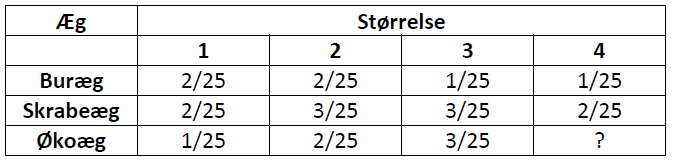

**Ved kontrol udtages tilfældige æg fra producenten.**

## 2.1 ØKOÆG STØRRELSE 4

For de marginale tæthedsfunktioner gælder, at

$f_X \left(x\right)=\sum_y f_{X,Y} \left(x,y\right)$, $\;\;\;f_Y \left(y\right)=\sum_x f_{X,Y} \left(x,y\right)$

Der gælder, at 


$$\sum_{x=1}^4 \sum_{y=1}^3 f_{X,Y} \left(x,y\right)=1$$


BatEgg = [2/25, 2/25, 1/25, 1/25];
BarnEgg = [2/25, 3/25, 3/25, 2/25];
EcoEgg = [1/25, 2/25, 3/25, 0];

EcoEgg(4) = 1 - (sum(BatEgg) + sum(BarnEgg) + sum(EcoEgg));

disp("Sandsynligheden for et økoæg af størrelsen 4 er " + EcoEgg(4));

Sandsynligheden for et økoæg af størrelsen 4 er 0.12


## 2.2 TILFÆLDIG ÆG STØRRELSE 3

Sandsynligheden for at et tilfældigt æg er af størrelsen 3, kan findes ved følgende udtryk.


$$f_X \left(x=3\right)=\sum_y f_{X,Y} \left(x=3,y\right)$$


Egg = [
        [2/25, 2/25, 1/25, 1/25]
        [2/25, 3/25, 3/25, 2/25] 
        [1/25, 2/25, 3/25, 3/25]
];

SizeThree = sum(Egg(:,3));

disp("Sandsynligheden for et tilfædigt æg med størrelse 3 er lig med " + SizeThree);

Sandsynligheden for et tilfædigt æg med størrelse 3 er lig med 0.28


## 2.3 TILFÆLDIG BURÆG

Sandsynligheden for at et tilfældigt æg er et buræg, kan findes ved følgende udtryk.


$$f_Y \left(y=1\right)=\sum_x f_{X,Y} \left(x,y=1\right)$$


BatEgg = sum(Egg(1, :));

disp("Sandsynligheden for et tilfældigt buræg er lig med " + BatEgg);

Sandsynligheden for et tilfældigt buræg er lig med 0.24


## 2.4 KONDITIONEL

Sandsynligheden for at det tilfældige udtagne æg er et skrabeæg givet,

at det er af størrelsen 2 kan beregnes ud fra følgende udtryk.


$$f_{Y|X} \left(y|x\right)=\frac{f_{X,Y} \left(x,y\right)}{f_X \left(x\right)}=P\left(Y=y,X=x\right)$$


hvor x = 2 og y er = 2.

BarnEggGivenSizeTwo = Egg(2, 2) / sum(Egg(:, 2));

disp("Sandsynligheden for at ægget er et" + ...
    " skrabeæg givet at størrelsen er 2, er lig med " + BarnEggGivenSizeTwo);

Sandsynligheden for at ægget er et skrabeæg givet at størrelsen er 2, er lig med 0.42857


# **3 STOKASTISK PROCESS**

**En stokastisk process er givet ved**

$X\left(n\right)=\alpha \cdot t$ for $t\ge 0$

**Hvor **$\alpha \sim N\left(1,\frac{1}{4}\right)$.

## 3.1 REALISATION

En skitsering af den stokastiske process $X\left(t\right)$ i intervallet $t=\left\lbrack 0;10\right\rbrack$ er bestemt som følgende.

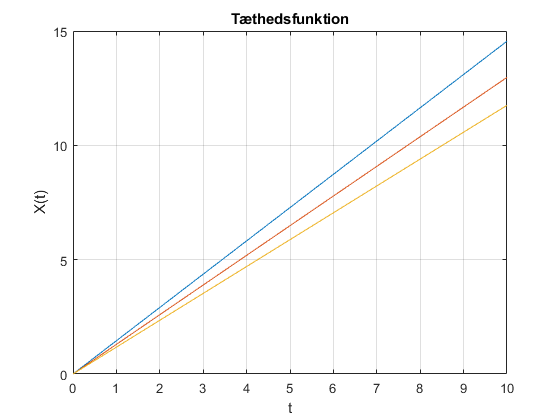

mu = 1;
sigma = sqrt(1/4);
t = 0:1:10;

for n = 1:3
   Realisation(n, :) = (ones(1, 11) * (sigma * randn + mu)) .* t;
end 

figure(3)
plot(t, Realisation(1, :));
hold on
plot(t, Realisation(2, :));
plot(t, Realisation(3, :));
grid on
title('Tæthedsfunktion')
ylabel('X(t)')
xlabel('t')
hold off

## 3.2 ENSEMBLE

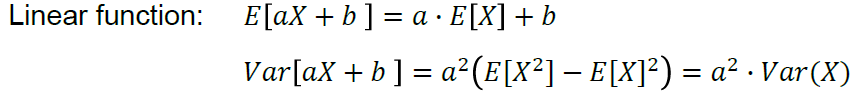

Da forventningsværdien til alpha, som er normaltfordelt, er lig med 1 kan middelværdien bestemmes som


$$E\left\lbrack X\right\rbrack =E\left\lbrack \alpha \cdot t\right\rbrack =E\left\lbrack \alpha \right\rbrack \cdot t=1\cdot t=t$$


Dertil er også anvendt at $X\left(t\right)$er en lineær funktion, hvilket også betyder at variansen kan bestemmes som følgende.


$$\mathrm{Var}\left\lbrack X\right\rbrack =\mathrm{Var}\left\lbrack \alpha \cdot t\right\rbrack =t^2 \cdot \mathrm{Var}\left(\alpha \right)=\frac{1}{4}t^2$$


## 3.3 PROCESSEN

Den stokastiske process er ikke WSS da både ensemble mean og ensemble variansen er afhængig af tiden.

Da processen ikke er WSS er den heller ikke ergodisk.

# **4 STATISTISK POISSION**

**En nyåbnet webshop forventer, at antallet af ordrer vil være poissonfordelt med et gennemsnit på 25 ordrer i timen.**

**Tidspunkterne for de enkelte ordrer antages at være uafhængige af hinanden.**

## 4.1 SANDSYNLIGHED EN TIME

For en poission fordeling gælder, at 


$$P\left(X=x\right)=\frac{\gamma^x }{x!}e^{-\gamma }$$


hvor $\gamma =\lambda \cdot t$. Dertil kan sansynligheden for noget mindre eller lig med x findes som


$$P\left(X\le x\right)=\mathrm{poisscdf}\left(x,\gamma \right)$$


altså ved brug af poission fordelingsfunktionen. Da der ønskes en sandsynlighed

for mere end 30 ordrer anvendes, at


$$P\left(X\ge x\right)=1-P\left(X\le x\right)$$


lambda = 25;
hours = 1;
orders = 30;

ProbabilityOverThirty = 1 - poisscdf(orders, hours * lambda);

disp("Sandsynligheden for at der indkommer mere end 30 ordrer på en time er " ... 
    + ProbabilityOverThirty);

Sandsynligheden for at der indkommer mere end 30 ordrer på en time er 0.13669


## 4.2 SANDSYNLIGHED FIRE TIMER

lambda = 25;
hours = 4;
orders = 80;

ProbabilityEightyOrLess = poisscdf(orders, hours * lambda);

disp("Sandsynligheden for at der indkommer 80 eller færre ordrer på en time er " ...
    + ProbabilityEightyOrLess);

Sandsynligheden for at der indkommer 80 eller færre ordrer på en time er 0.022649


**Over en periode på 24 timer registreres 653 ordrer på webshoppen.**

## 4.3 ESTIMEREDE ANTAL ORDRER

Forventningsværdien for en poissionfordeling kan bestemmes som


$$E\left\lbrack X\right\rbrack =t\cdot \lambda =\gamma$$



$$\lambda =\frac{E\left\lbrack X\right\rbrack }{t}=\frac{\gamma }{t}$$


hours = 24;
orders = 653;

obs = orders / hours;

disp("Det estimerede antal ordre pr. time er nu " + obs + " ordre pr. time");

Det estimerede antal ordre pr. time er nu 27.2083 ordre pr. time


## 4.4 OBSERVERET VS. ANTAGELSE

For at tjekke om det observerede antal ordrer stemmer overns med antagelsen om et gennemsnit på 25 ordrer i timen benyttes p-værdien.

Den bestemmes ved først at beregne en Z-score.

Dernæst kan p-værdien beregnes som 


$$p=2\cdot |1-\Phi \left(|z|\right)|$$


Der opstilles to hypoteser i forbindelse med denne opgave hvor null hypotesen 

antager, at antallet af ordre pr. time er 25. Samt en alternativ hypotese der antager,

at antallet af order pr. time er forskellig fra 25.


$$H_0 :$$
  
$$\lambda =25$$



$$H_1 :$$
  
$$\lambda \not= 25$$


Z antages at være normalfordelt $Z\sim N\left(0,1\right)$.

Z = (orders - hours * lambda) / sqrt(hours * lambda);

PValue = 2 * (1 - normcdf(Z, 0, 1));

disp("p værdien er bestemt til at være lig med " ...
    + PValue + " og dermed kan null hypotesen forkastes.");

p værdien er bestemt til at være lig med 0.030486 og dermed kan null hypotesen forkastes.


disp("Det antal observerede antal ordre stemmer altså ikke overens med antagelsen");

Det antal observerede antal ordre stemmer altså ikke overens med antagelsen


## 4.5 KONFIDENSINTERVAL

konfidensintervallet for antallet af ordre i timen ud fra observationen kan bestemmes som 


$$\lambda_{\pm } =\frac{1}{t}\left\lbrack x+\frac{1\ldotp {96}^2 }{2}\pm 1\ldotp 96\cdot \sqrt{x+\frac{1\ldotp {96}^2 }{4}}\right\rbrack$$


a = orders + (1.96^2)/2;
b = 1.96 * sqrt(orders + (1.96^2)/4);

Lambda.min = 1/hours * (a-b);
Lambda.max = 1/hours * (a+b);

disp("95% konfidensinterval er bestemt til at være [" + Lambda.min + ";" + Lambda.max + "]");

95% konfidensinterval er bestemt til at være [25.1999;29.3768]
